Usando observador para estimar as velocidades v e r

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

t_ = 0:0.01:60;
dim= size( t_ );
dimT = dim(2);


Matrizes

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];
    

D = zeros(1,3);

E = [1/m_u;1/m_v;0]; %entrada de disturbio

B_novo = [B E];

D_novo = [D zeros(size(C,1),size(E,2))];


Por LQR

Q = diag([50000,45000,40000]);

R_ = diag([0.002,0.0004,0.005]);

[K, P_, E_]= lqr(A,B,Q,R_); 

F = A-B*K; 




Descretização e condições iniciais e entradas

x0 = [0;0;0];

u1_ = zeros(size(t_));

for i = 1:1:500
    u1_(i) = 0;
 
end

for i = 501:1:dimT
    u1_(i) = 0;
   
end

u2_ = 0*ones(size(t_));


w = 10*sin(2*pi()*0.1*t_);


u3_ = zeros(size(t_));

u_ = [u1_;u2_;u3_;w];

u_2 = [u1_;u2_;u3_];





Para o Observador

Cch = eye(3);

Q_obs = diag([10, 10, 66]);

R_obs = diag([0.5,0.5,0.5]);

[K_obs ,P_obs ,E_obs] = lqr(A.', Cch.', Q_obs, R_obs);
F_obs = (A-K_obs'*Cch);

L = K_obs';



Sistema com x e x^

Gamma = [A-B*K, B*K;
         zeros(3,3), A-K_obs'*Cch];

Bsis = [B; B];

Bsis_novo = [B_novo;B_novo];

Csis = [eye(6)];

Dsis = [zeros(6,3)];
Dsis_novo = [zeros(6,4)];

x_obs = zeros(3, 1);
xch_obs = 0.1*ones(3, 1);
cond_inicial = [x_obs; xch_obs];


Aa = [A, -B*K;
    L*Cch, (A-L*Cch-B*K)];

sys1 = ss(F,B_novo,C,D_novo); %LQR controlador

sys2 = ss(Gamma, Bsis_novo, Csis, Dsis_novo); %sistema do observador de estados 

sys3 = ss(Aa, Bsis_novo, Csis, Dsis_novo); %Controlador dinâmico baseado no Observador


U1 = ones(1, dimT);
U0 = zeros (1, dimT);
U_ = [U0; U0; U0];


y1 = lsim(sys1, u_, t_ ,x0); %controlador

y2 = lsim(sys2, u_, t_, cond_inicial); %observador

[y3, t2, xlq3] = lsim(sys3, u_, t_ ,cond_inicial); %controlador com observador
xlq3;
xlq = xlq3(:,4:6);

Integrais para achar a posição

ulq = K*xlq';


u1 = U + y1(:,1);
%v2 = V + y3(:,2);
%r1 = R + y1(:,1);
u3 = U + y3(:,4);
v3 = V + y3(:, 5);
r3 = R + y3(:, 6);

Psi = cumtrapz(t_, r3);

% Psi_real = cumtrapz(t_, r1);
% r1 = R + y1(:, 3);

% Vtx1 = u1*cos(Psi') - v3*sin(Psi');
% Vty1 = u1*sin(Psi') + v3*cos(Psi');
% Vtx = diag(Vtx1);
% Vty = diag(Vty1);
% Tjx =  cumtrapz(t_, Vtx);
% Tjy =  cumtrapz(t_, Vty);

Vtx1 = u3*cos(Psi') - v3*sin(Psi');
Vty1 = u3*sin(Psi') + v3*cos(Psi');
Vtx = diag(Vtx1);
Vty = diag(Vty1);
Tjx =  cumtrapz(t_, Vtx);
Tjy =  cumtrapz(t_, Vty);

Plots

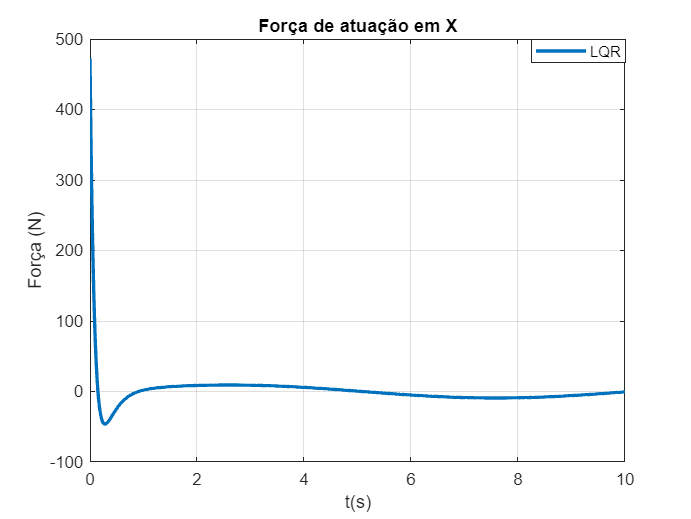

figure (1)
plot(t_, ulq(1,:), 'LineWidth', 2)
grid on 
legend('LQR')
title('Força de atuação em X')
xlabel('t(s)')
ylabel('Força (N)')
xlim([0 10])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

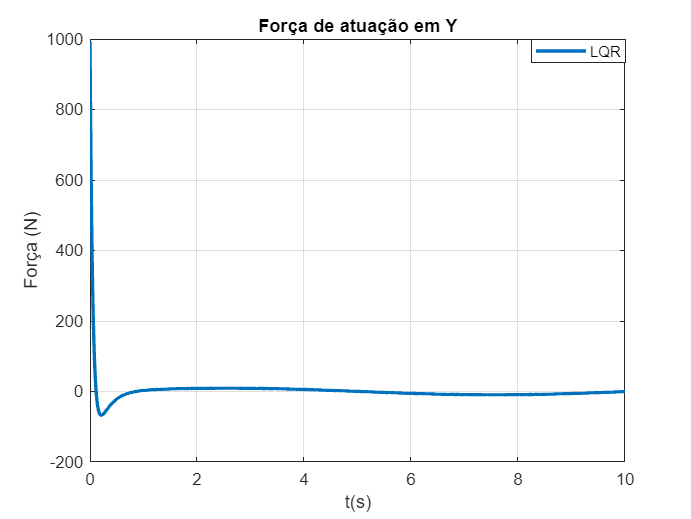


figure (1)
plot(t_, ulq(2,:), 'LineWidth', 2)
grid on 
legend('LQR')
title('Força de atuação em Y')
xlabel('t(s)')
ylabel('Força (N)')
xlim([0 10])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

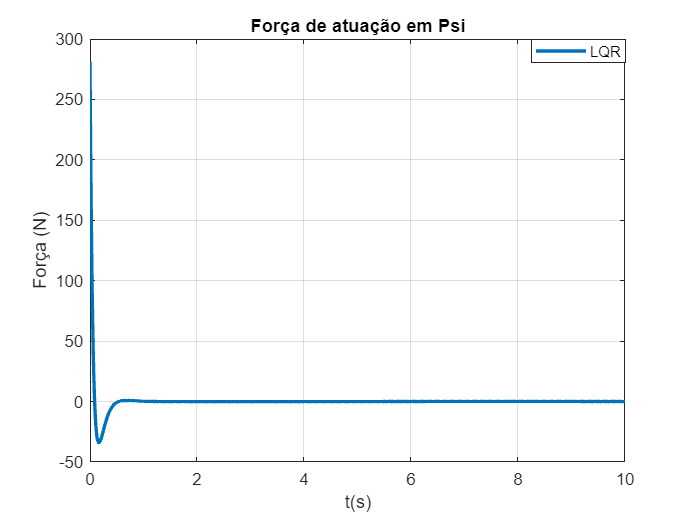


figure (1)
plot(t_, ulq(3,:), 'LineWidth', 2)
grid on 
legend('LQR')
title('Força de atuação em Psi')
xlabel('t(s)')
ylabel('Força (N)')
xlim([0 10])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

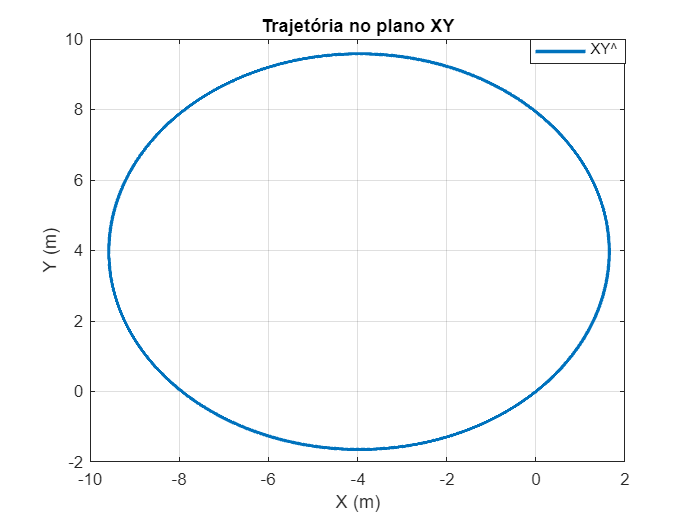



figure(1)
plot(Tjx,Tjy, 'LineWidth', 2)
grid on
title('Trajetória no plano XY') 
xlabel('X (m)')
ylabel('Y (m)') 
legend('XY\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

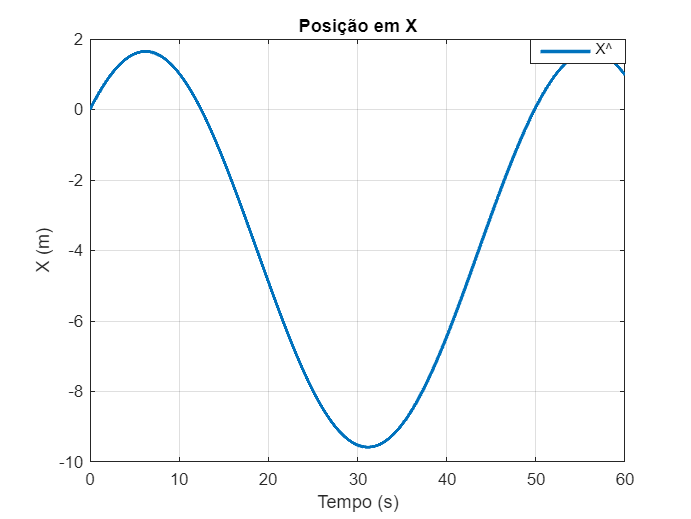



figure(2)
plot(t_,Tjx, 'LineWidth', 2)
grid on
title('Posição em X') 
xlabel('Tempo (s)')
ylabel('X (m)') 
legend('X\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

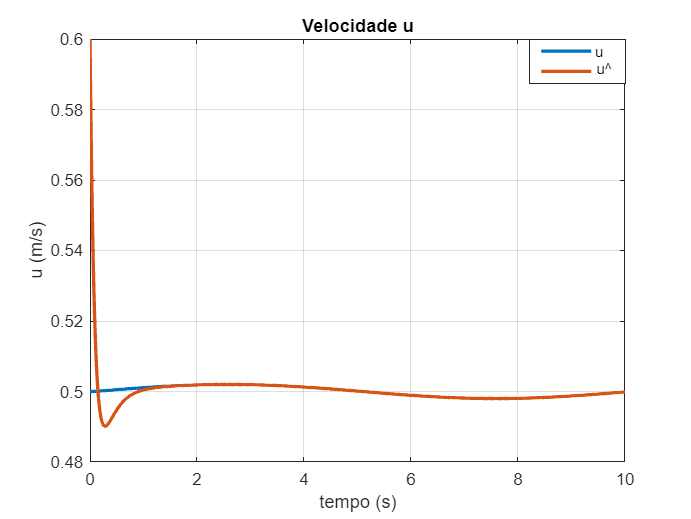



figure(3)
plot(t_, u1,t_, u3, 'LineWidth', 2)
grid on
title('Velocidade u') 
xlabel('tempo (s)') 
ylabel('u (m/s)')
legend('u', 'u\^')
xlim([0 10])
legend("Position", [0.76572,0.83931,0.13907,0.085501])

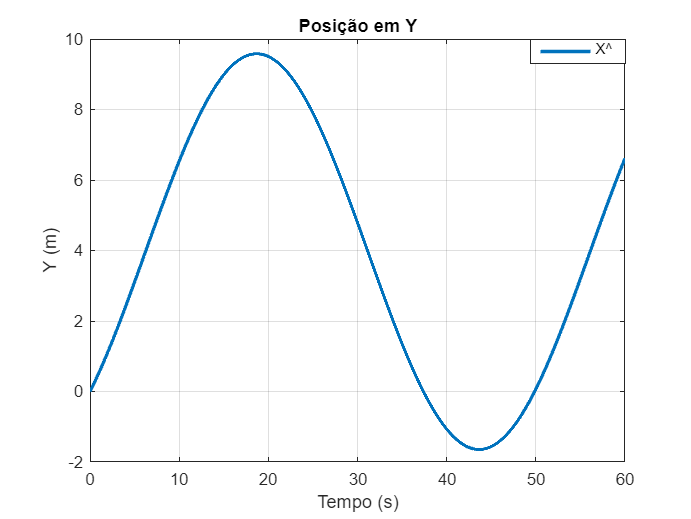



figure(4)
plot(t_,Tjy, 'LineWidth', 2)
grid on
title('Posição em Y') 
xlabel('Tempo (s)')
ylabel('Y (m)') 
legend('X\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

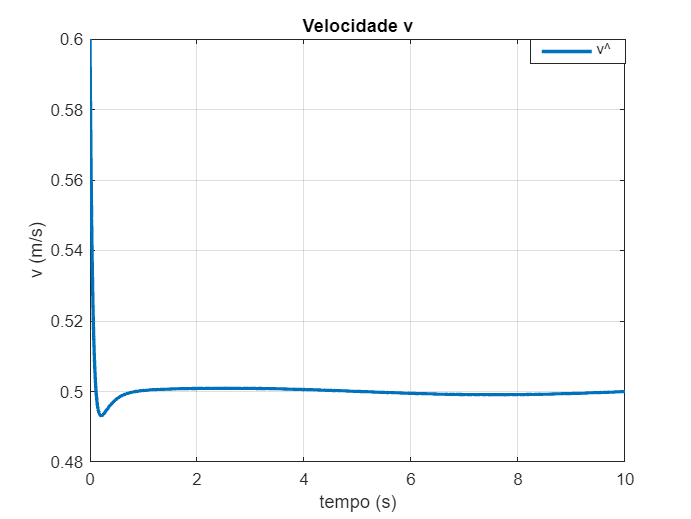



figure(5) 
plot(t_, v3, 'LineWidth', 2) 
grid on
title('Velocidade v') 
xlabel('tempo (s)')
ylabel('v (m/s)') 
legend('v\^') 
xlim([0 10])
legend("Position", [0.76796,0.87846,0.13748,0.045761])

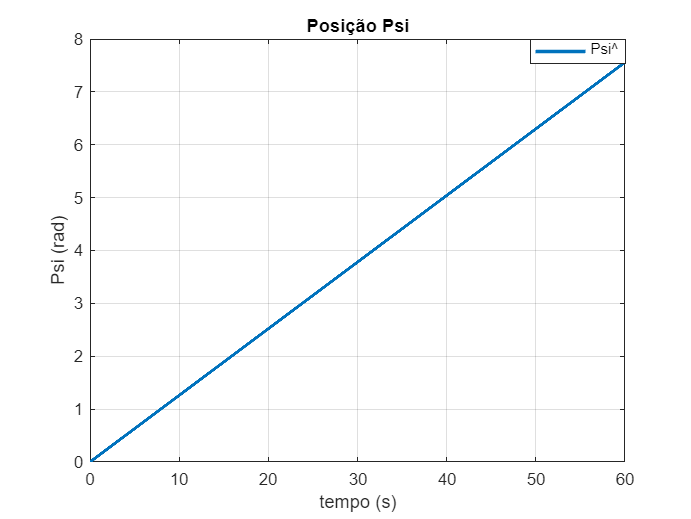



figure(6)
plot(t_,Psi, 'LineWidth', 2)
grid on
title('Posição Psi') 
xlabel('tempo (s)')
ylabel('Psi (rad)') 
legend('Psi\^') 
legend("Position", [0.76796,0.87846,0.13748,0.045761])

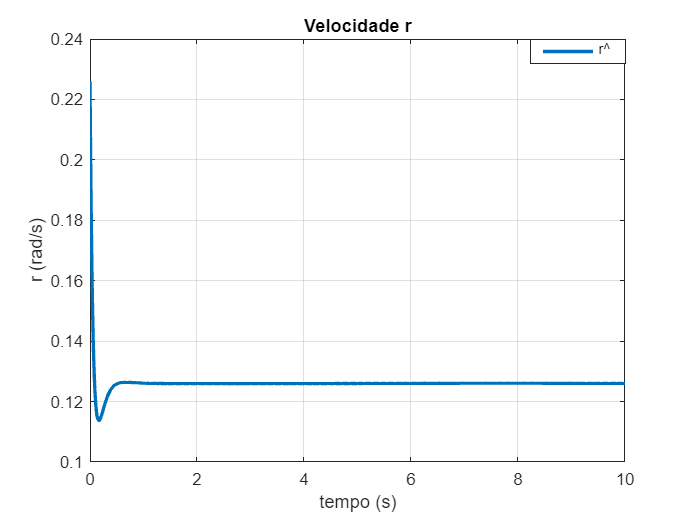




figure(7)  
plot(t_, r3, 'LineWidth', 2)
grid on 
title('Velocidade r') 
xlabel('tempo (s)')
ylabel('r (rad/s)') 
legend('r\^') 
xlim([0 10])
legend("Position", [0.76796,0.87846,0.13748,0.045761])



p = pzmap(sys2);
grid on